# FEM Structual Analysis of Pinion Gear

## Requirement

- MATLAB 2021a

- Partial Differential Equation Toolbox

## Analysis Table

%Analysis Table
tmp = {
        'Title'  'StlFile'  'YoungsModulus'   'PoissonsRatio'   'FixedFaceNo' 'LoadFaceNo'  'Preassure'  ;   
         'Type1 Teeth Stress'  'pinion_gear_6t_1.stl'   1e9 0.3 [70 69] [41 41]  1.5e7 ;
         'Type2 Teeth Stress'  'pinion_gear_6t_2.stl'   1e9 0.3 [105 77]  [41 41] 1.5e7    ;
         'Type1 Hole Stress'  'pinion_gear_6t_1.stl'   1e9 0.3 [54] [53]  1e7 ;
         'Type2 Hole Stress'  'pinion_gear_6t_2.stl'   1e9 0.3 [54]  [55] 1e7   ;
       };
AnalysisTable = cell2table(tmp(2:end,:));
AnalysisTable.Properties.VariableNames = tmp(1,:);

AnalysisNo = [1:4]; %Analysis No
N=length(AnalysisNo);
Tbl = AnalysisTable(AnalysisNo,:) 

Tbl = 4×7 table
            Title                     StlFile             YoungsModulus    PoissonsRatio    FixedFaceNo    LoadFaceNo    Preassure
    ______________________    ________________________    _____________    _____________    ___________    __________    _________

    {'Type1 Teeth Stress'}    {'pinion_gear_6t_1.stl'}        1e+09             0.3         {[ 70 69]}     {[41 41]}      1.5e+07 
    {'Type2 Teeth Stress'}    {'pinion_gear_6t_2.stl'}        1e+09             0.3         {[105 77]}     {[41 41]}      1.5e+07 
    {'Type1 Hole Stress' }    {'pinion_gear_6t_1.stl'}        1e+09             0.3         {[    54]}     {[   53]}        1e+07 
    {'Type2 Hole Stress' }    {'pinion_gear_6t_2.stl'}        1e+09             0.3       

## Create Structural Analysis Model

for i=1:N 
    model(i) = createpde('structural','static-solid');
    importGeometry(model(i),Tbl.StlFile{i});
    generateMesh(model(i));

end

## Display 3D Model with Face Label

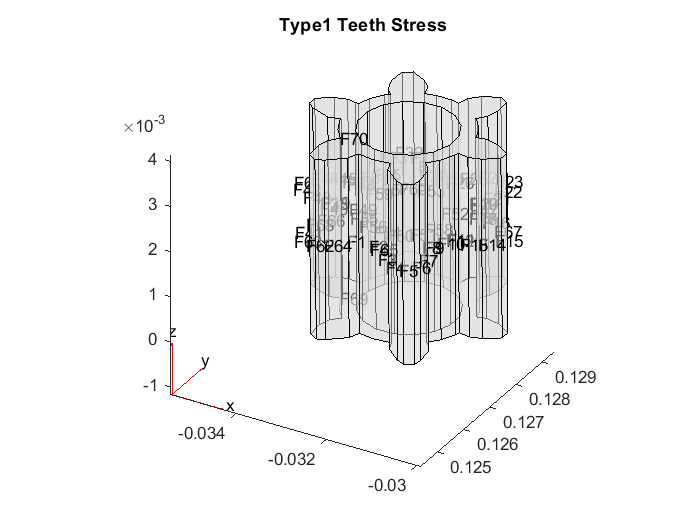

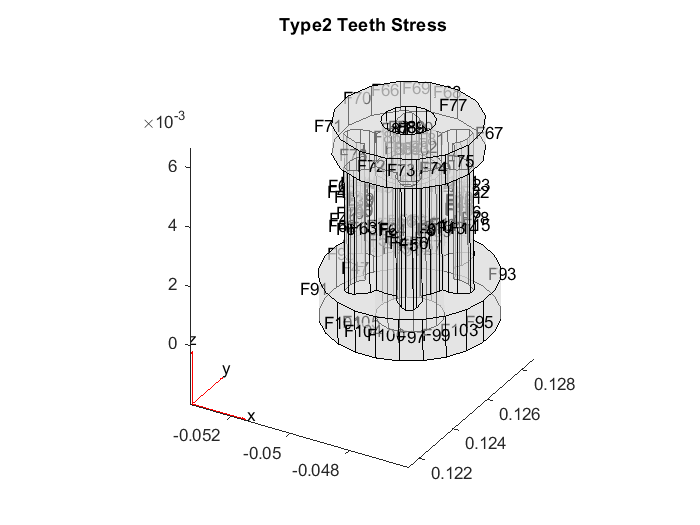

[s,tbl_i]=unique(Tbl.StlFile);
for i=[tbl_i]'
    figure;
    pdegplot(model(i),'FaceLabels','on','FaceAlpha',0.5);
    title(Tbl.Title(i));
    view(30,30);
end

## Specify Structural Properties of Material and Preassure

for i=1:N
    structuralProperties(model(i),'YoungsModulus',Tbl.YoungsModulus(i), ...
                           'PoissonsRatio',Tbl.PoissonsRatio(i));
    structuralBC(model(i),'Face',Tbl.FixedFaceNo{i},'Constraint','fixed');

    structuralBoundaryLoad (model(i),'Face',Tbl.LoadFaceNo{i},'Pressure',Tbl.Preassure(i));
end

## Calculate Solution

for i=1:N
    result(i) = solve(model(i));
end

## Plot Displacement Components

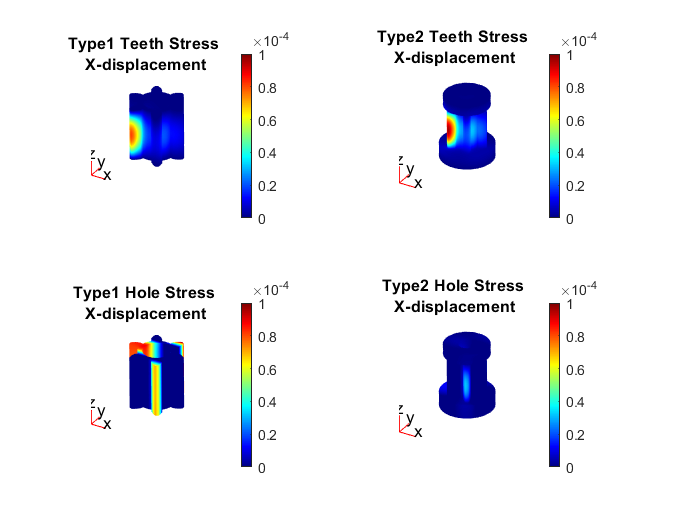

figure;
for i=1:N
    subplot(ceil(N/PlotCol),PlotCol,i);
    pdeplot3D(model(i),'ColorMapData',result(i).Displacement.ux);
    title([Tbl.Title(i) " X-displacement"]);
    colormap('jet');
    caxis([0 1e-4]);
end

## Plot von Mises Stress

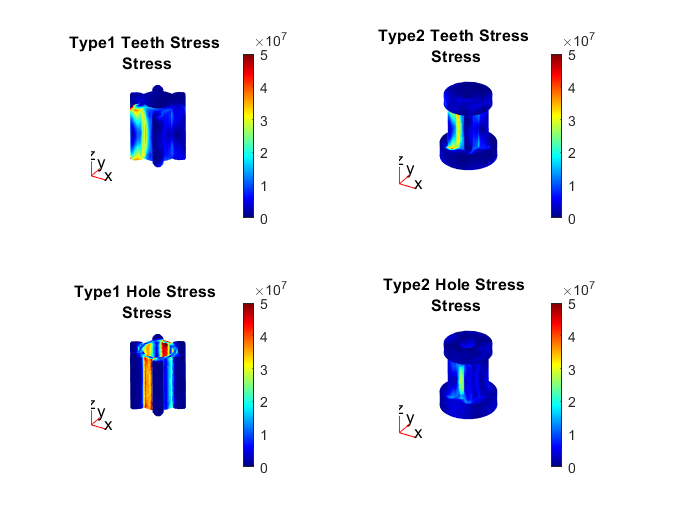

figure;
for i=1:N
    subplot(ceil(N/PlotCol),PlotCol,i);
    pdeplot3D(model(i),'ColorMapData',result(i).VonMisesStress);
    title([Tbl.Title(i) " Stress"]);
    colormap('jet');
    caxis([0 5e7]);
end

## Reference

- [Partial Differential Equation Toolbox Example>Deflection Analysis of Bracket](https://mathworks.com/help/pde/ug/deflection-analysis-of-a-bracket.html)